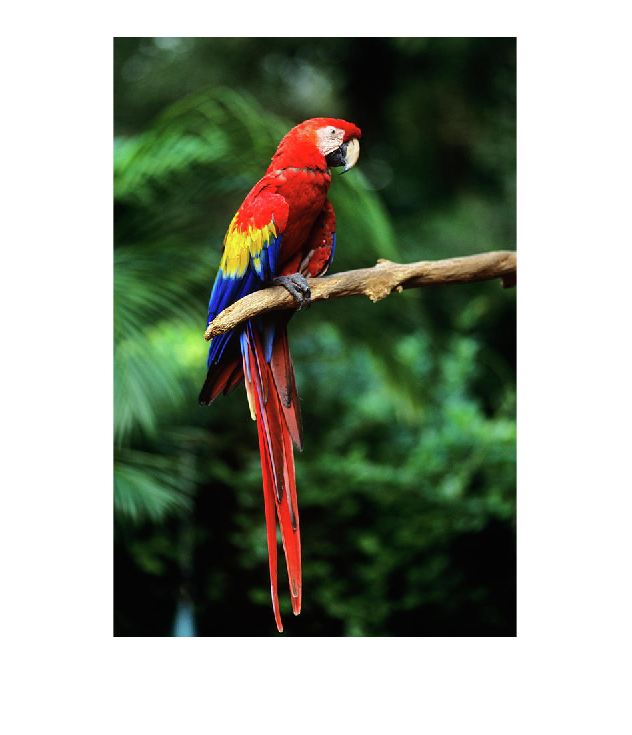

img = imread('parrot.jpg');
imshow(img)

LABimg = rgb2lab(img);

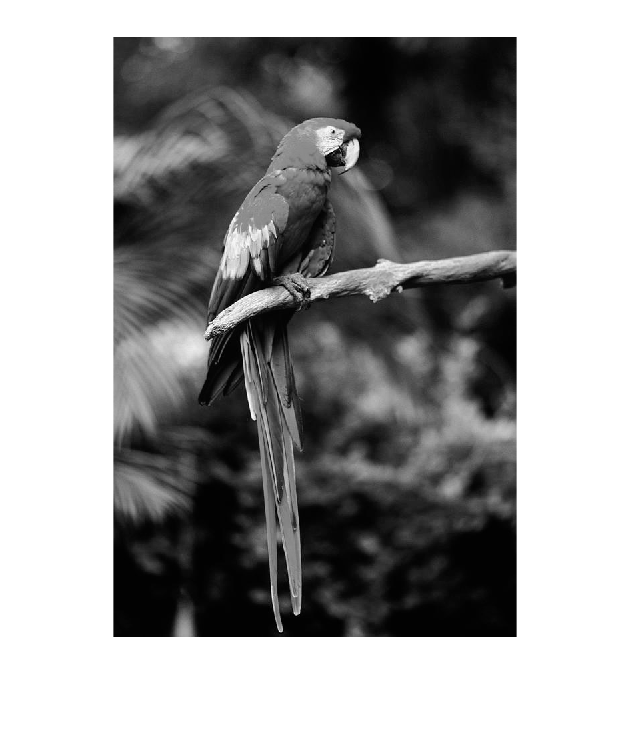

subplot(1,1,1)
imshow(LABimg(:,:,1),[0 100])

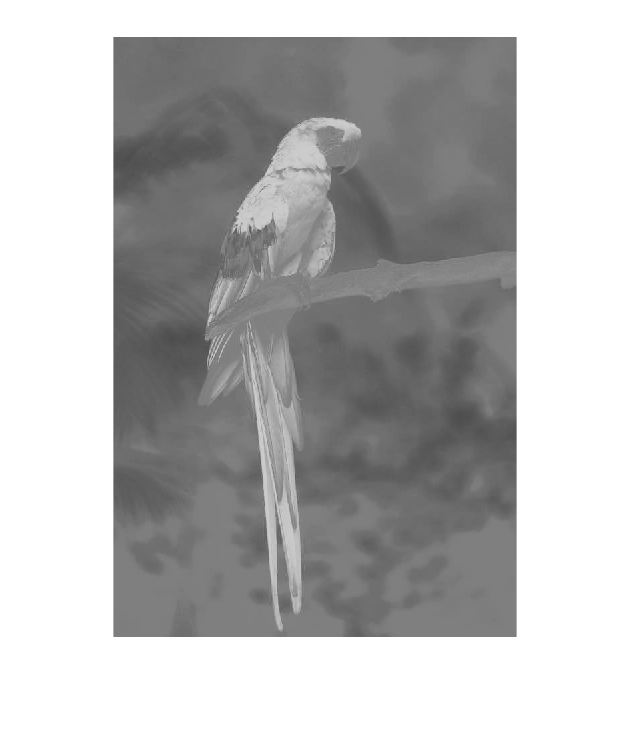

imshow(LABimg(:,:,2),[-127 128])

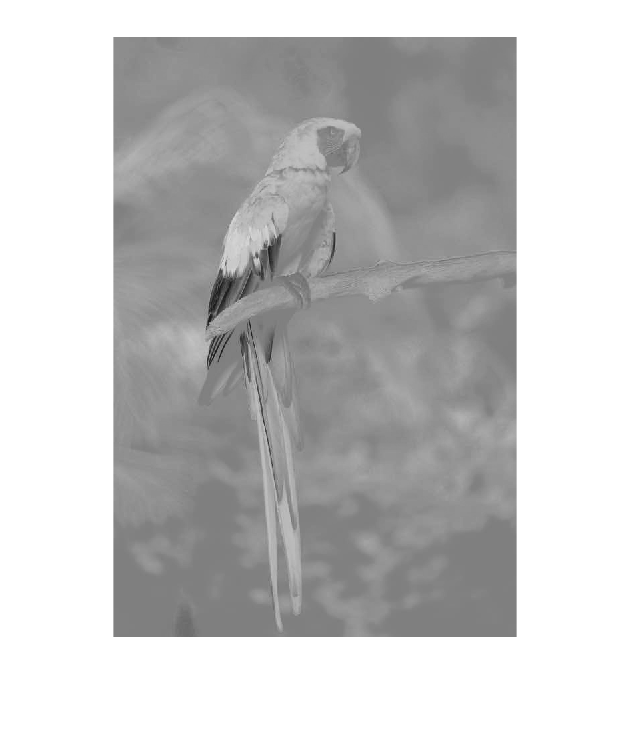

imshow(LABimg(:,:,3),[-127 128])

%cmap for a channel
cMap1 = interp1([0;1],[0 1 0; 1 0 0],linspace(0,1,256));
%cmap for b channel
cMap2 = interp1([0;1],[0 0 1; 1 1 0],linspace(0,1,256));

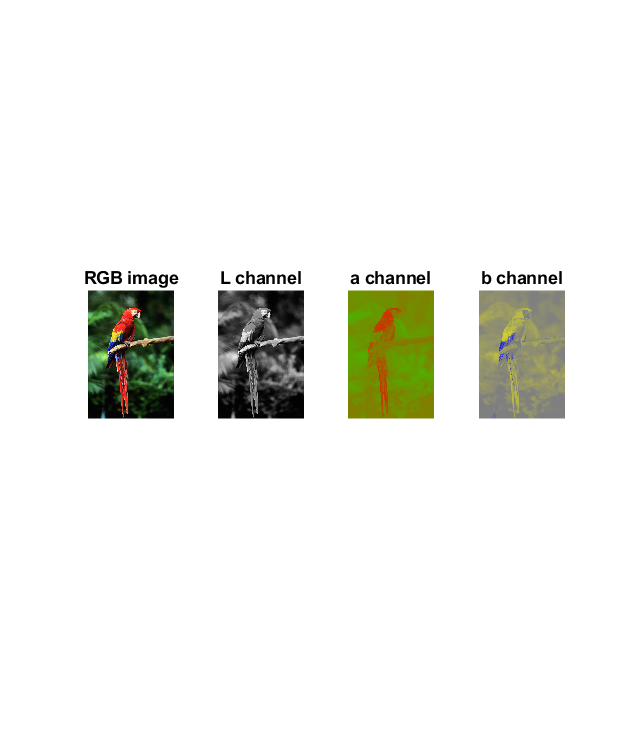

subplot(1, 4, 1);
imshow(img);
title('RGB image', 'FontSize', 20);
subplot(1, 4, 2);
imshow(LABimg(:, :, 1), [0 100]);
title('L channel', 'FontSize', 20);
ax(3) = subplot(1, 4, 3);
imshow(LABimg(:, :, 2), [-127 128]);
colormap(ax(3), cMap1)
title('a channel', 'FontSize', 20);
ax(4) = subplot(1, 4, 4);
imshow(LABimg(:, :, 3), [-127 128]);
colormap(ax(4), cMap2)
title('b channel', 'FontSize', 20);

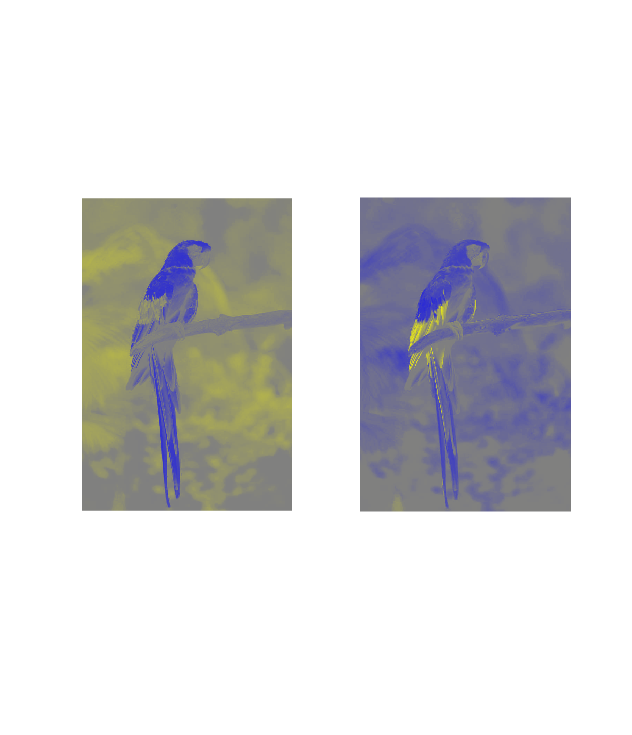

subplot(1,2,1);
imshow(LABimg(:, :, 2), [-127 128])
colormap(cMap1)

subplot(1,2,2);
imshow(LABimg(:, :, 3), [-127 128])
cMap2 = interp1([0;1],[1 1 0; 0 0 1],linspace(0,1,256));
colormap(cMap2)